# Envelope Rhythm Metrics

## The vocalic energy amplitude envelope

addpath(genpath('.'));
file = ['.' filesep 'envmetrics' filesep 'example.wav'];
[x,wavFs] = audioread(file);

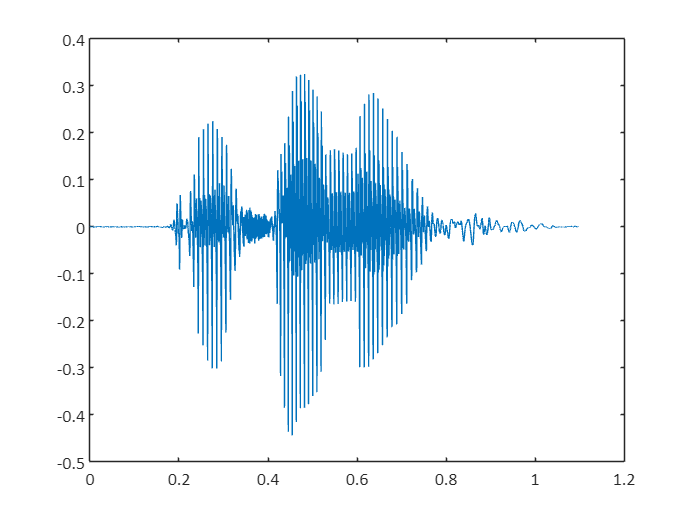

t = (0:length(x)-1)/Fs;
figls; plot(t,x)

#### Extract envelope

par.bandpass = [400 4000];  %: vocalic energy bandpass range (there is no a priori justification for this range)
par.lowpass = 10;           %: lowpass filtering cutoff
par.Fs = wavFs;                %: sampling rate
par.ds = 100;               %: downsampling factor

%extract the envelope:
[env,t_env,x_bp] = envm_band_energy(x,par);

#### Plot envelope superimposed over waveform

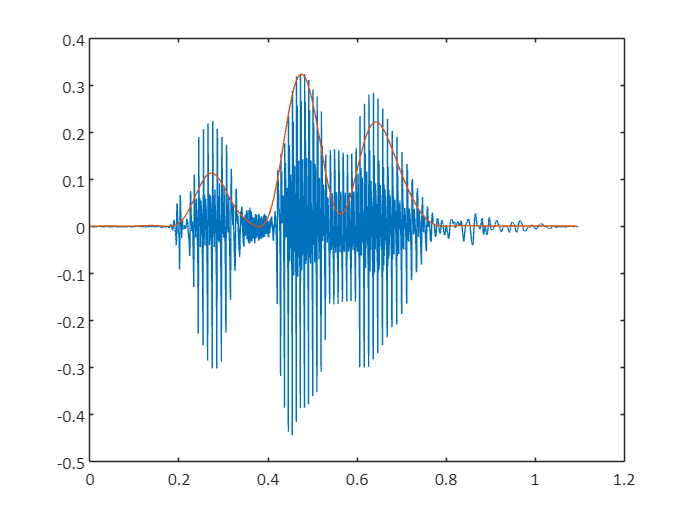

env = env-min(env);
env = env/max(env)*max(x);

figls; plot(t,x); hold on; plot(t_env,env); 

The envelope is technically a "vocalic energy amplitude envelope", obtained from a low-pass zero-phase filtering of the absolute value of a band-pass filtered signal. The vocalic energy band is defined in `par.bandpass. `For this reason, the envelope fits the magnitude of the vocalic energy waveform better than it fits the original signal.

#### Plot envelope superimposed over magnitude of vocalic energy waveform

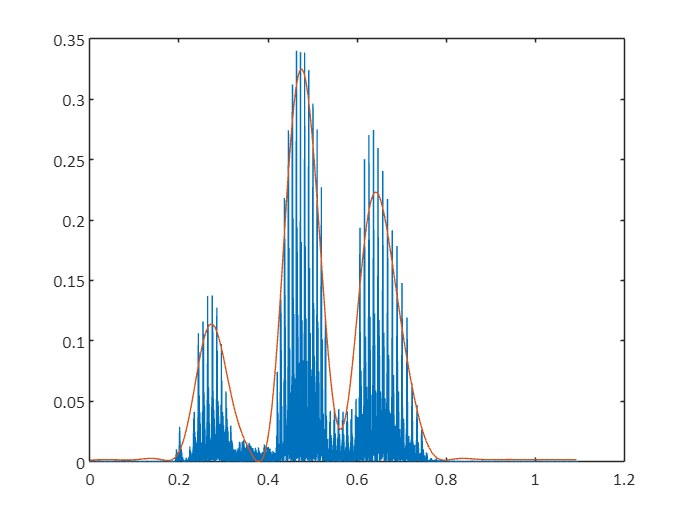

figls; plot(t,abs(x_bp)); hold on; plot(t_env,env);

## Low-frequency Fourier Analysis (LFFA)

#### Pre-processing

Envelope rhythm metric analyses are usually applied to chunks of speech. First the envelope is zero-centered and rescaled:

env = env-mean(env);
env = env/max(abs(env));

The recentered envelope will generally be non-zero at its edges, so a tukeywindow is applied:

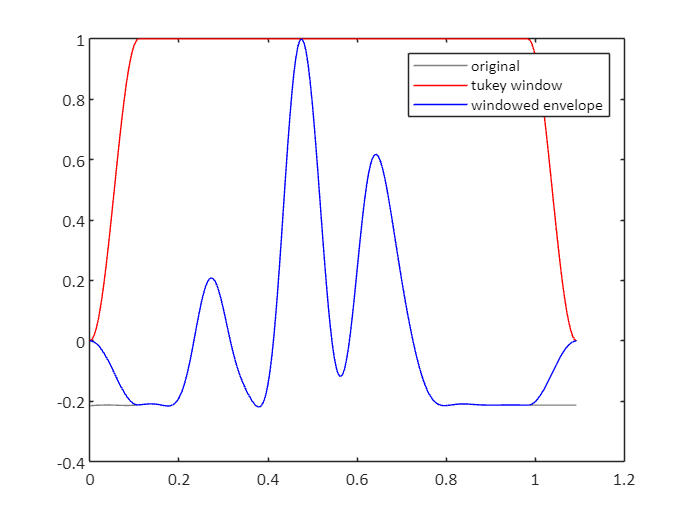

tw = tukeywin(length(env),0.2);
envw = env.*tw;
figls; plot(t_env,env,'color',[.5 .5 .5]); hold on; plot(t_env,tw,'r'); plot(t_env,envw,'b');
legend({'original','tukey window','windowed envelope'})

#### Smoothed power spectrum

%smoothed power spectrum
par.nfft = 2048;  %number of dft coefficients (should be > envelope length)
par.sm_Hz = 1; %smoothing bandwidth
par.Fs = wavFs/par.ds; %envelope sampling rate

[smpsd,f] = envm_smoothed_psd(envw,par);

#### Plot smoothed power spectrum

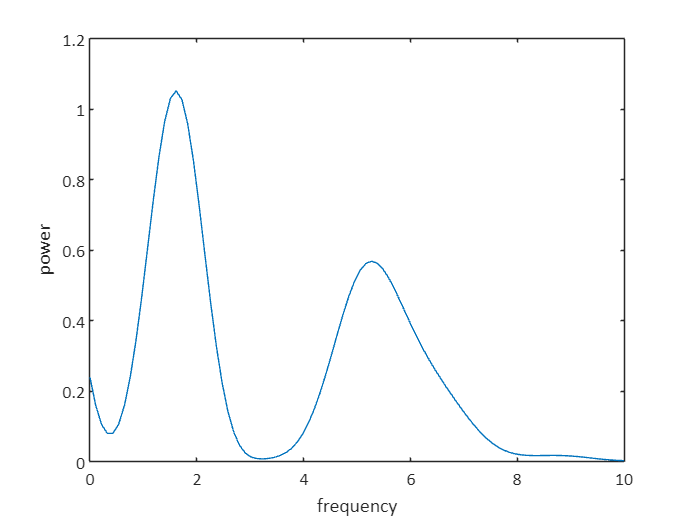

figls; plot(f,smpsd); hold on; xlim([0 par.lowpass]);
xlabel('frequency'); ylabel('power');

#### Obtain LFFA metrics

par.powerratio_freq_bins = [1 3.5 10];
par.centroid_freq_bins = [1 10];

LFFA = envm_psd_metrics(smpsd,f,par);
disp(LFFA)

     sbpr_1: 0.9817
    scntr_1: 3.6840



#### Spectral band power ratios

For each frequency band between the bin edges defined in `par.powerratio_freq_bins`, the `sbpr` is the ratio of power in the two bands. 

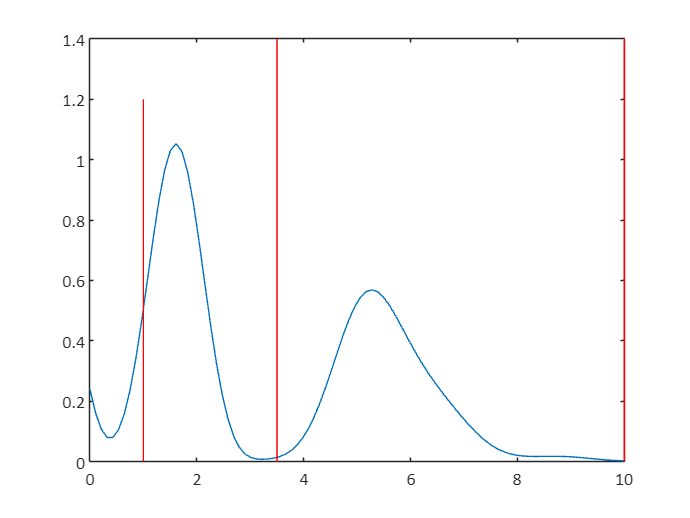

figls; plot(f,smpsd); hold on; xlim([0 par.lowpass]);
for i=1:length(par.powerratio_freq_bins)
    plot(par.powerratio_freq_bins(i)*[1 1],ylim,'r-');
end

#### Spectral center of gravity

The spectral center of gravity is centroid of the power in the frequency range specified in each row of `par.centroid_frequency_bins`:

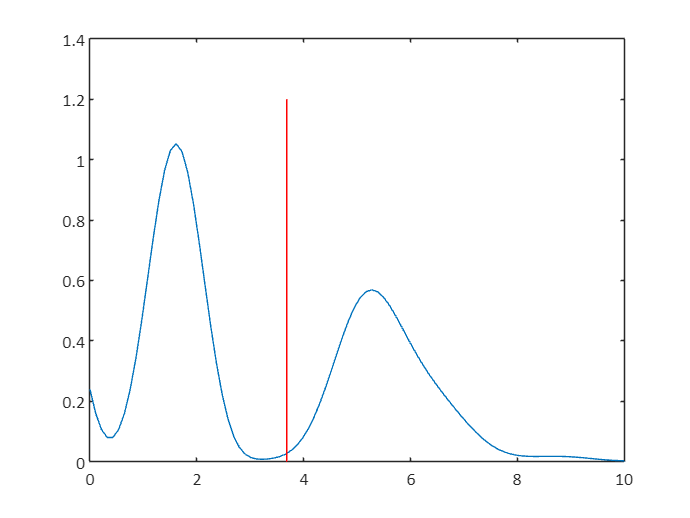

figls; plot(f,smpsd); hold on; xlim([0 par.lowpass]);
plot(LFFA.scntr_1*[1 1],ylim,'r-');

## Empirical mode decomposition metrics

par.Fs = wavFs/par.ds; %envelope sampling rate

% empirical mode decomposition (EMD) / Hilbert-Huang transform (HHT)
% using a modified version of Alan Tan's toolbox:
% (http://www.mathworks.com/matlabcentral/fileexchange/19681-hilbert-huang-transform/content/plot_hht.m) 
[imf,w,t_imf] = envm_hht(envw,1/par.Fs);

%using matlab built-in functions (close but not quite identical to the toolbox):
% imf = emd(envw,'SiftRelativeTolerance',0.1,'MaxNumIMF',4);
% [hs,~,t_imf,w] = hht(imf,par.Fs);
% imf = num2cell(imf,1);
% w = num2cell(w,1);

#### Plot the intrinsic mode functions from EMD

The first IMF captures syllable-timescale oscillation, the second IMF captures stress-timescale oscillation. Higher-order IMFs can capture phrase-timescale oscillations

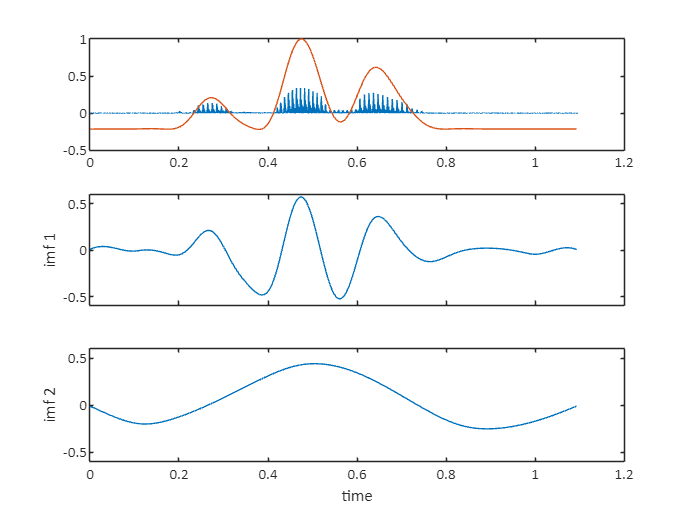

figls;
Nimf = 2; %usually only the first two or three IMFs are analyzed
subplt = @(i)subplot(Nimf+1,1,i);
subplt(1); plot(t,abs(x_bp)); hold on; plot(t_env,env);
ax=[];
for i=1:Nimf
    ax(i) = subplt(i+1);  plot(t_env,imf{i});
    ylabel("imf " + i);
end
linkaxes(ax,'y'); set(ax(1:end-1),'XTicklabel',[]); xlabel('time')

#### Processing the instantaneous frequencies of the IMFs

The frequencies are not meaningful where the IMF is not oscillating, so we remove edge values and values outside of expected ranges:

%Remove edge values:
edgedur = 0.1;

for i=1:length(w) %loop over chunks
        w{i}(1:round(par.Fs*edgedur)) = nan;
        w{i}(end-round(par.Fs*edgedur)+1:end) = nan;    
end

%Remove out-of-range values
lower_bound = 0;
upper_bound = 13.16; %frequency at which magnitude response of 4th order butterworth is -10dB
for i=1:length(w) %loop over IMFs
    w{i}(w{i}<lower_bound) = nan;
    w{i}(w{i}>upper_bound) = nan;
end

#### Plotting the instantaneous frequencies

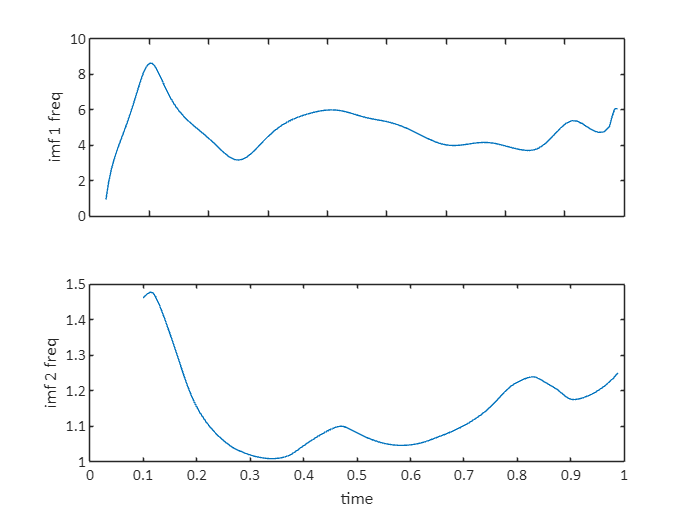

figls;
subplt = @(i)subplot(Nimf,1,i);
ax=[];
for i=1:Nimf
    ax(i) = subplt(i);  plot(t_imf(1:length(w{i})),w{i});
    ylabel("imf " + i + " freq");
end
set(ax(1:end-1),'XTicklabel',[]); xlabel('time');

#### Obtain EMD metrics

EMD = envm_emd_metrics(imf,w);
disp(EMD);

        pow_imf: [33.8030 47.9953 2.5518 0.1125]
           mu_w: [4.9155 1.1355 0.8696 0.2896]
          var_w: [1.4334 0.0120 0.0019 0.0015]
           sd_w: [1.1972 0.1096 0.0441 0.0388]
    imf_ratio21: 1.4199



#### IMF powers

These are the powers of the IMFs, defined as $\sum_t |\mathrm{imf}(t)|$

#### IMF average frequencies

The average frequency of each IMF

#### IMF frequency standard deviations

The standard deviations of the instantaneous frequencies of each IMF, reflecting the stability of the rhythm on the corresponding timescale of the IMF

#### IMF power ratios

The ratio of power in the 2nd IMF (stress-timescale) to power in the 1st IMF (syllable-timescale)

## Batch processing

The function `envm_metrics_batch` is designed to process a set of waveforms. It minimally requires a cell array of waveforms (which are usuallly chunks of speech) and a structure that specifies the sampling rate of the audio (which must be the same for all chunks), e.g.

files = "." + filesep + 'envmetrics' + filesep + ["example.wav"; "example2.wav"];
X={};
for i=1:length(files)
    [X{i},par.Fs] = audioread(files(i));
end

%uses default parameters:
METRICS = envm_metrics_batch(X,par);

disp(METRICS)

    sbpr_1    scntr_1    imf_ratio21    pow_imf1    pow_imf2    pow_imf3    mu_w1     mu_w2     mu_w3     var_w1     var_w2     var_w3     sd_w1      sd_w2      sd_w3 
    ______    _______    ___________    ________    ________    ________    ______    ______    ______    ______    ________    _______    ______    _______    _______

    1.0241    3.6274        1.5032       34.339      51.617         NaN     5.0428    1.1275       NaN    2.6562    0.078999        NaN    1.6298    0.28

#### Parameters for batch processing

The following parameters can be specified:

disp(envm_default_params)

              paramName                    value                                  description                          
    ______________________________    _______________    ______________________________________________________________

    {'bandpass'                  }    {[    400 NaN]}    {'bandpass filter edges. NaN = determine from sampling rate.'}
    {'lowpass'                   }    {[         10]}    {'lowpass filter cutoff'                                     }
    {'ds'                        }    {[        100]}    {'downsampling factor'                                       }
    {'tukeywin_param'            }    {[     0.1000]}    {'tukey window parameter for envelopes'                      }
    {'nfft'                      }    {[       2048]}    {'number of dft coefficients'                                }
    {'sm_Hz'                     }    {[          1]}    

function [] = figls()
figure('Position',[0 0 640 480]);
end